#  Calculus of Variations

## Introduction

In ES112 and ES122, you have discussed how to find stationary values of functions of a single variable $f\left(x\right)$, of several variables $f\left(x, y, \dots\right)$  and of constrained variables, where $x$, $y$, $\dots$ are subject to the $n$ constraints $h_k\left(x, y, \dots\right) = 0,\,k = 1,2,\dots,n$. In all these cases the forms of the functions $f$  and $h_k$  were known, and the problem was one of finding the appropriate values of the variables $x$, $y$ etc.

We now turn to a different kind of problem in which we are interested in bringing about a particular condition for a given expression (usually maximising or minimising it) by varying the functions on which the expression depends. For instance, we might want to know in what shape a fixed length of rope should be arranged so as to enclose the largest possible area, or in what shape it will hang when suspended under gravity from two fixed points. In each case we are concerned with a general maximisation or minimisation criterion by which the function $y\left(x\right)$  that satisfies the given problem may be found.

The calculus of variations provides a method for finding the function $y\left(x\right)$ . The problem must first be expressed in a mathematical form, and the form most commonly applicable to such problems is an integral. In each of the above questions, the quantity that has to be maximised or minimised by an appropriate choice of the function $y\left(x\right)$ may be expressed as an integral involving $y\left(x\right)$ and the variables describing the geometry of the situation.

In our example of the rope hanging from two fixed points, we need to find the shape function $y\left(x\right)$ that minimises the gravitational potential energy of the rope. Each elementary piece of the rope has a gravitational potential energy proportional both to its vertical height above an arbitrary zero level and to the length of the piece. Therefore the total potential energy is given by an integral for the whole rope of such elementary contributions. The particular function $y\left(x\right)$ for which the value of this integral is a minimum will give the shape assumed by the hanging rope.

So in general we are led by this type of question to study the value of an integral whose integrand has a specified form in terms of a certain function and its derivatives, and to study how that value changes when the form of the function is varied. Specifically, we aim to find the function that makes the integral stationary, i.e. the function that makes the value of the integral a local maximum or minimum. Note that, unless stated otherwise, $y ^\prime$  is used to denote $\displaystyle \frac{\mathrm{d}\!y}{\mathrm{d}x}$  throughout this chapter. We also assume that all the functions we need to deal with are sufficiently smooth and differentiable.

## The Euler–Lagrange equation

Let us consider the integral


$$I\left[y\right]=\int_{a} ^{b} f\left(x,y,y ^\prime\right)\,\mathrm{d}x$$


where $a$ , $b$  and the form of the function $f$  are fixed by given considerations, e.g. the physics of the problem, but the curve $y\left(x\right)$  is to be chosen so as to make stationary the value of $I$, which is clearly a function (or more accurately a *functional*) of this curve. We wish to find the function $y\left(x\right)$  such that first-order small changes in it will make only second-order changes in the value of $I$.

Writing this in a more mathematical form, let us suppose that $y ^\star \left(x\right)$ is the function required to make $I$ *stationary* and consider making the replacement


$$y\left(x\right) = y ^\star\left(x\right) + \delta\!y\left(x\right)$$


where the parameter $\delta\!y\left(x\right)$is the *variation* of $y$ with sufficiently amenable mathematical properties. We can see that the operator $\delta$ and $\displaystyle \frac{\mathrm{d}}{\mathrm{d}x}$ commute:


$$\frac{\mathrm{d}}{\mathrm{d}x}\left(\delta\!y\left(x\right)\right) = \frac{\mathrm{d}}{\mathrm{d}x}\left(y\left(x\right)-y ^\star\left(x\right)\right) = \frac{\mathrm{d}}{\mathrm{d}x}\left(y\left(x\right)\right) - \frac{\mathrm{d}}{\mathrm{d}x}\left(y ^\star\left(x\right)\right) = \delta\left(\frac{\mathrm{d}}{\mathrm{d}x}\left(y\left(x\right)\right)\right)$$


The increment in $f$ is then given by


$$\Delta f = f\left(x,y,y ^\prime\right) - f\left(x,y ^\star,y ^{\star\prime}\right) \approx \frac{\partial f}{\partial y}\left(x,y ^\star,y ^{\star\prime}\right)\,\delta\!y + \frac{\partial f}{\partial y ^\prime}\left(x,y ^\star,y ^{\star\prime}\right)\,\delta\!y ^\prime\,.$$


The last expression is called the variation of $f$


$$\delta f = \frac{\partial f}{\partial y}\left(x,y ^\star,y ^{\star\prime}\right)\,\delta\!y + \frac{\partial f}{\partial y ^\prime}\left(x,y ^\star,y ^{\star\prime}\right)\,\delta\!y ^\prime$$


and is similar to the differential but we consider here the dependent variables $y\left(x\right)$ and $y ^\prime\left(x\right)$ to vary and not the independent variable $x$.

The increment in $I$ is evaluated similarly:


$$\matrix{\Delta I &=& \int_a ^b f\left(x,y,y ^{\prime}\right)\,\mathrm{d}x - \int_a ^b f\left(x,y ^\star,y ^{\star\prime}\right)\,\mathrm{d}x \cr&=& \int_a^b \Delta f\left(x,y,y ^{\prime}\right)\,\mathrm{d}x \approx \int_a^b \left(\frac{\partial f}{\partial y}\left(x,y ^\star,y ^{\star\prime}\right)\,\delta\!y + \frac{\partial f}{\partial y ^\prime}\left(x,y ^\star,y ^{\star\prime}\right)\,\delta\!y ^\prime\right)\,\mathrm{d}x}$$


The last expression is called the *first order variation* of $I$. To have a stationary value, we require


$$\delta I = \int_a ^b \left(\frac{\partial f}{\partial y}\left(x,y ^\star,y ^{\star\prime}\right)\,\delta\!y + \frac{\partial f}{\partial y ^\prime}\left(x,y ^\star,y ^{\star\prime}\right)\,\delta\!y ^\prime\right)\,\mathrm{d}x = 0\,.$$


The second term can be integrated by parts


$$\left[\frac{\partial f}{\partial y ^\prime}\left(x,y ^\star,y ^{\star\prime}\right)\,\delta\!y\right] ^b_a + \int_a^b\left(\frac{\partial f}{\partial y}\left(x,y ^\star,y ^{\star\prime}\right)-\frac{\mathrm{d}}{\mathrm{d}x}\left(\frac{\partial f}{\partial y ^\prime}\left(x,y ^\star,y ^{\star\prime}\right)\right)\right)\,\delta\!y\,\mathrm{d}x=0\,.$$


In order to simplify the result we will assume, for the moment, that the end-points are fixed, i.e. not only $a$  and $b$  are given but also $y\left(a\right)$ and $y\left(b\right)$. This restriction means that we require $\delta\!y\left(a\right) = \delta\!y\left(b\right) = 0$, in which case the first term on the LHS equals zero at both end-points. Since the expression must be satisfied for an arbitrary variation $\delta\!y$, it is easy to see that we require


$$\frac{\partial f}{\partial y}\left(x,y ^\star,y ^{\star\prime}\right)-\frac{\mathrm{d}}{\mathrm{d}x}\left(\frac{\partial f}{\partial y ^\prime}\left(x,y ^\star,y ^{\star\prime}\right)\right) = 0$$


This is known as the *Euler–Lagrange equation*, and is a differential equation for $y ^\star\left(x\right)$, since $f\left(x, y, y ^\prime\right)$ is known.

***Note:*** Euler's equation can be written in the form

$\frac{\mathrm d}{\mathrm dx}\left(f-y\prime\frac{\partial f}{\partial y\prime}\right)-\frac{\partial f}{\partial x}=0$.

If $f$ does not involve $x$ explicitly, the Euler equation can be integrated to


$$f-y\prime\frac{\partial f}{\partial y\prime}=c$$


        **Example 1.** Find the shortest distance between two points using polar coordinates.

The relation between polar coordinates $\left(r, \varphi\right)$ and Cartesian coordinates $\left(x, y\right)$ is


$$\matrix{x &=& r \cos\varphi \qquad &\Rightarrow \qquad \mathrm{d}x = \cos\varphi\,\mathrm{d}r - r \sin\varphi\,\mathrm{d}\phi\cr y &=& r \sin\varphi \qquad &\Rightarrow \qquad \mathrm{d}y = \sin\varphi\,\mathrm{d}r + r \cos\varphi\,\mathrm{d}\phi}$$


The elementary distance in Cartesian coordinates is given by


$$\mathrm{d}s=\sqrt{\left(\mathrm{d}x\right) ^2+\left(\mathrm{d}y\right) ^2}\,.$$


Hence, in polar coordinates, we have


$$\mathrm{d}s=\sqrt{\left(\mathrm{d}r\right) ^2 + r ^2 \left(\mathrm{d}\varphi\right) ^2}.$$


We choose $\varphi$  as independent variable and so the problem becomes that of finding the curve which minimizes the integral


$$I = \int_{\varphi_a}^{\varphi_b} \sqrt{\left(\frac{\mathrm{d}r}{\mathrm{d}\varphi}\right) ^2 + r^2}\,\mathrm{d}\varphi$$


The Euler-Lagrange equation for this problem is


$$\frac{\partial f}{\partial r}\left(\varphi, r ^\star,\frac{\mathrm{d}r ^\star}{\mathrm{d}\varphi}\right) - \frac{\mathrm{d}}{\mathrm{d}\varphi}\frac{\partial f}{\partial r_\varphi}\left(\varphi, r ^\star,\frac{\mathrm{d}r ^\star}{\mathrm{d}\varphi}\right) = \frac{r ^\star}{\sqrt{r ^{\star 2} + r_\varphi ^{\star 2}}} - \frac{\mathrm{d}}{\mathrm{d}\varphi} \left(\frac{r_\varphi ^{\star}}{\sqrt{r ^{\star 2} + r_\varphi ^{\star 2}}}\right) = 0$$


where $f\left(\varphi, r,\frac{\mathrm{d}r}{\mathrm{d}\varphi}\right)=\sqrt{\left(\frac{\mathrm{d}r}{\mathrm{d}\varphi}\right) ^2 + r^2}$  and $\displaystyle r_\varphi = \frac{\mathrm{d}r}{\mathrm{d}\varphi}$. We obtain the ordinary (non-linear) differential equation


$$r ^\star \frac{\mathrm{d} ^2 r ^\star}{\mathrm{d}\varphi ^2} - 2 \left(r_\varphi ^\star\right) ^2 - r ^{\star 2} = 0$$


% This can be found using Matlab. We omit the trivial solution of r = 0
syms phi real
syms r(phi)
dr = diff(r,1,phi);
exp = simplify(r/sqrt(r^2 + dr^2) - diff(dr / sqrt(r^2 + dr^2), phi))

$$exp(phi) = \frac{r\left(\varphi \right)\,\left(-r\left(\varphi \right)\,\frac{\partial^{2}}{\partial \varphi^{2}}r\left(\varphi \right)+2\,{\left(\frac{\partial }{\partial \varphi }r\left(\varphi \right)\right)}^{2}+{r\left(\varphi \right)}^{2}\right)}{{\left({\left(\frac{\partial }{\partial \varphi }r\left(\varphi \right)\right)}^{2}+{r\left(\varphi \right)}^{2}\right)}^{3/2}}$$

which has solution


$$r ^\star\left(\varphi\right) = p\sec\left(\varphi - \beta\right)$$


where $p$ and $\beta$ are constants of integration. 

% Solving non-linear equations is beyond the scope of the course, but you can verify that
% this is indeed a solution:
syms p beta real
rs = p*sec(phi - beta);
simplify(subs(exp, r, rs))

$$ans(phi) = 0$$

This solution is the polar form for the equation of a straight line. Here $p$ has the geometrical interpretation of representing the perpendicular distance from the origin to the line and $\beta$  has the geometrical interpretation of representing the inclination (in radians) of the normal line which passes through the origin.

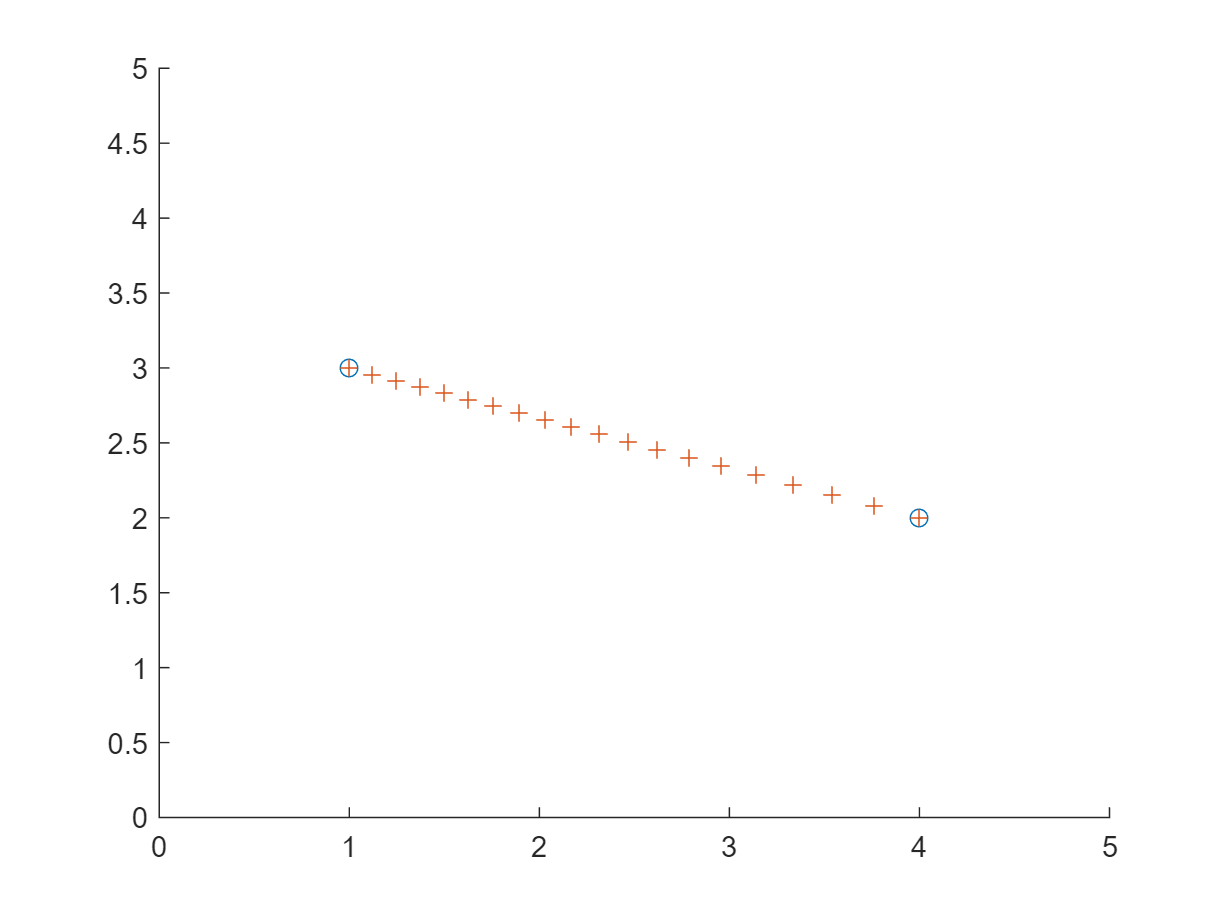

%% Illustration
% data
xa = 4; ya = 2; ra = sqrt(xa^2 + ya^2); phia = atan(ya/xa);
xb = 1; yb= 3; rb = sqrt(xb^2 + yb^2); phib = atan(yb/xb);
% determine p and beta
sol = solve([ra == p*sec(phia - beta), rb == p*sec(phib - beta)],[p, beta]);
ps = sol.p(1);
betas = sol.beta(1);
% generate intermediate points according to our solution
phis = linspace(phia, phib, 20);
rs = ps * sec(phis - betas);
% plot
figure
scatter([xa xb], [ya yb])
hold on
scatter(rs .* cos(phis), rs .* sin(phis), Marker="+")
xlim([0 5]); ylim([0 5]);

        **Example 2.** A wire in a vertical plane connects origin $O$ and point $P_1(x_1,y_1)$. A bead of mass $m$ placed at $O$ slides without friction down the wire to $P_1$ under the influence of gravity. Find the shape of the wire so that the bead goes from $O$ to $P_1$ in the least time.

Assume that at time $t$ the bead is at $P(x, y)$ and that arc $OP = s$*. *Then from mechanics we have 

	Kinetic energy at $O$ + Potential energy at $O$* = *Kinetic energy at $P$ + Potential energy at $P$, or


$$0+mg0=\frac{1}{2}m\left(\frac{\mathrm ds}{\mathrm dt}\right)^2+mg(0-y)$$


i.e. $\left(\frac{\mathrm ds}{\mathrm dt}\right)^2=2gy$ or $\frac{\mathrm ds}{\mathrm dt}=\sqrt{2gy}$.

Thus the time for the bead to go from $O$ to $P_1$ is


$$\int_0^T\mathrm dt=T=\int_{x=0}^{x=x_1}\frac{1}{\sqrt{2gy}}\mathrm ds=\frac{1}{\sqrt{2g}}\int_0^{x_1}\frac{\sqrt{1+y\prime^2}}{\sqrt y}\mathrm dx$$


The time will be a minimum when the integral is a minimum. Letting $f(x,y,y\prime)=\frac{\sqrt{1+y\prime^2}}{\sqrt y}$

clear
syms x c
syms a positive
syms y(x) Dy(x)
f = sqrt(1+Dy^2)/(sqrt(y(x)));
eq = simplify(f - Dy * functionalDerivative(f, Dy)) == c

$$eq(x) = \frac{1}{\sqrt{y\left(x\right)}\,\sqrt{{\mathrm{Dy}\left(x\right)}^{2}+1}}=c$$

eq = subs(eq, c, 1/sqrt(a))

$$eq(x) = \frac{1}{\sqrt{y\left(x\right)}\,\sqrt{{\mathrm{Dy}\left(x\right)}^{2}+1}}=\frac{1}{\sqrt{a}}$$

which simplifies to $y^\prime = \sqrt{\frac{a-y}{y}}$.

Separating variables and integrating,

clear
syms x c
syms a positive
syms y(x)
syms y theta
h = sqrt((a-y)/y);
eq = int(1/h, y) + c == x

$$eq = c-y\,\sqrt{\frac{a}{y}-1}-a\,\mathrm{atan}\left(\sqrt{\frac{a}{y}-1}\right)=x$$

% Not possible to obtain an explicit form for y(x)
solve(eq, y)

ans =
Empty sym: 0-by-1


% Solution: change of variables
g = a*sin(theta)^2;
g = combine(g, 'sincos')

$$g = \frac{a}{2}-\frac{a\,\cos\left(2\,\theta \right)}{2}$$

Dg = diff(g, theta);
h = subs(h, y, g)*Dg

$$h = a\,\sin\left(2\,\theta \right)\,\sqrt{\frac{\frac{a}{2}+\frac{a\,\cos\left(2\,\theta \right)}{2}}{\frac{a}{2}-\frac{a\,\cos\left(2\,\theta \right)}{2}}}$$

eq = int(1,x) == rewrite(expand(int(h, theta)),['sin']) + c

$$eq = x=c+\frac{\sqrt{2}\,a\,{\sin\left(\theta \right)}^{2}\,\sqrt{1-{\sin\left(\theta \right)}^{2}}}{\sqrt{2\,{\sin\left(\theta \right)}^{2}}}-\frac{\sqrt{2}\,a\,\theta \,\sin\left(\theta \right)\,\left(2\,{\sin\left(\frac{\theta }{2}\right)}^{2}-1\right)}{\sqrt{2\,{\sin\left(\theta \right)}^{2}}\,\sqrt{1-{\sin\left(\theta \right)}^{2}}}$$

So, $x=c+\frac{a}{2}(\sin2\theta-2\theta)$.

Thus the parametric equations of the curves are given by

$x=b(\phi-\sin\phi)+c$ and $y=b(1-\cos\phi)$

where $b=\frac{a}{2}$ and $\phi=2\theta$. Since the curves passes through the origin we must have $k=0$ so that the required equations are

$x=b(\phi-\sin\phi)$ and $y=b(1-\cos\phi)$

The constant $b$ is determined from the fact that the curve must pas through $(x_1, y_1)$.

The curve represented by these equations is a *cycloid* and is the path of a fixed point A on a circle of radius $b$ as it rolls along the $x$ axis.

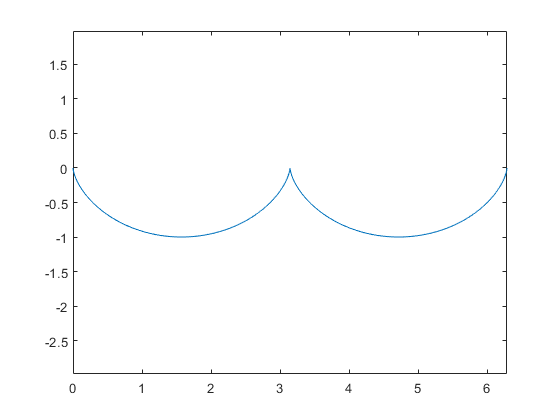

b = -0.5;
phi = 0:sign(b)*0.1:8*b*pi;
x = b*(phi-sin(phi));
y = b*(1-cos(phi));
plot(x,y)
axis equal

The problem is often called the *brachistochrone problem *from the Greek words *brachistos *meaning *shortest *and *chronos *meaning *time. *

## Extensions

### Several dependent variables

Here we have $f\left(t, x, y, z, \dot x, \dot y, \dot z\right)$. The analysis in this case proceeds as before, 

$\delta I[x^\star]=0$, $\delta I[y^\star]=0$, $\delta I[z^\star]=0$

leading to 3 separate but simultaneous equations


$$\matrix{\frac{\partial f}{\partial x}\left(t,x ^\star, y ^\star, z ^\star, \dot x ^\star, \dot y ^\star, \dot z ^\star\right)-\frac{\mathrm{d}}{\mathrm{d}t}\left(\frac{\partial f}{\partial \dot x}\left(t,x ^\star, y ^\star, z ^\star, \dot x ^\star, \dot y ^\star, \dot z ^\star\right)\right) &=& 0\cr \frac{\partial f}{\partial y}\left(t,x ^\star, y ^\star, z ^\star, \dot x ^\star, \dot y ^\star, \dot z ^\star\right)-\frac{\mathrm{d}}{\mathrm{d}t}\left(\frac{\partial f}{\partial \dot y}\left(t,x ^\star, y ^\star, z ^\star, \dot x ^\star, \dot y ^\star, \dot z ^\star\right)\right) &=& 0\cr \frac{\partial f}{\partial z}\left(t,x ^\star, y ^\star, z ^\star, \dot x ^\star, \dot y ^\star, \dot z ^\star\right)-\frac{\mathrm{d}}{\mathrm{d}t}\left(\frac{\partial f}{\partial \dot z}\left(t,x ^\star, y ^\star, z ^\star, \dot x ^\star, \dot y ^\star, \dot z ^\star\right)\right) &=& 0}$$


### Higher order functionals

We consider the functional


$$I[y]=\int_{x_1}^{x_2}f(x,y,y\prime,y\prime\prime)\,\mathrm dx\,,$$


where the integrand is a function of the variables $x$ , $y$ , $y\prime$ and $y\prime\prime$. We assume that $y(x)$ and all its derivatives are continuous over the interval $(x_1,x_2)$ and that the integral exists. The function $f(x)$is subject to the following boundary conditions 

$y(x_1)=y_ 1$, $y\prime(x_1)=y_1\prime$, $y(x_2)=y_2$, $y\prime(x_2)=y_2\prime$, 

where the quantities $y_1$, $y_1\prime$, $y_2$ and $y_2\prime$ are given constants. We use the variational notation to find the differential equation satisfied by the function $y^\star(x)$ which produces a stationary value for the integrand $I[y]$. If this stationary value corresponds to an extremal, the first variation is required to be zero


$$\delta I_{1}=\int_{x_{1}}^{x_{2}}\left(\frac{\partial f}{\partial y^{\star}}\delta y+\frac{\partial f}{\partial y^{\star\prime}}\delta y^{\prime}+\frac{\partial f}{\partial y^{\star\prime\prime}}\delta y^{\prime\prime}\right)\mathrm d x=0\,$$


where $\delta y=\delta y^{\prime}=0$ at the end points. We integrate the second term by parts


$$\int_{x_{1}}^{x_{2}}\frac{\partial f}{\partial y^{\star\prime}}\delta y^{\prime}\mathrm d x=\left[\frac{\partial f}{\partial y^{\star\prime}}\delta y\right]_{x_{1}}^{x_{2}}-\int_{x_{1}}^{x_{2}}\frac{\mathrm dx}{\mathrm dx}\left(\frac{\partial f}{\partial y^{\star\prime}}\right)\delta y\mathrm d x\,,$$


where the first term is zero because of the boundary conditions. We now integrate the third term in the first variation by parts


$$\int_{x_{1}}^{x_{2}}\frac{\partial f}{\partial y^{\star\prime\prime}}\delta y^{\prime\prime}\mathrm d x=\left[\frac{\partial f}{\partial y^{\star\prime\prime}}\delta y^{\prime}\right]_{x_{1}}^{x_{2}}-\int_{x_{1}}^{x_{2}}\frac{\mathrm dx}{\mathrm d x}\left(\frac{\partial f}{\partial y^{\star\prime\prime}}\right)\delta y^{\prime}\mathrm d x\,,$$


where again the first term is zero because of the boundary conditions. Performing another integration by parts, yields


$$\int_{x_{1}}^{x_{2}}\frac{\partial f}{\partial y^{\star\prime\prime}}\delta y^{\prime\prime}\mathrm d x=-\left[\frac{\mathrm d}{\mathrm d x}\left(\frac{\partial f}{\partial y^{\star\prime\prime}}\right)\delta y\right]_{x_{1}}^{x_{2}}+\int_{x_{1}}^{x_{2}}\frac{\mathrm d^{\,2}}{\mathrm d x^{2}}\left(\frac{\partial f}{\partial y^{\star\prime\prime}}\right)\delta y\mathrm d x\,,$$


where again the first term is zero because of the boundary conditions. Therefore, the first variation is simplified to the equation


$$\delta I_{1}=\int_{x_{1}}^{x_{2}}\left(\frac{\partial f}{\partial y^{\star}}-\frac{\mathrm d}{\mathrm d x}\left(\frac{\partial f}{\partial y^{\star\prime}}\right)+\frac{\mathrm d^{\,2}}{\mathrm d x^{2}}\left(\frac{\partial f}{\partial y^{\star\prime\prime}}\right)\right)\delta y\mathrm d x=0\,.$$


Now, we can use the basic lemma to obtain the Euler-Lagrange necessary condition for a stationary value 


$$\frac{\partial f}{\partial y^{\star}}-\frac{\mathrm d}{\mathrm d x}\left(\frac{\partial f}{\partial y^{\star\prime}}\right)+\frac{\mathrm d^{\,2}}{\mathrm d x^{2}}\left(\frac{\partial f}{\partial y^{\star\prime\prime}}\right)=0\,.$$


### Several independent variables

We now consider functionals with more than one independent variable and a single dependent variable. Let $w(x,y)$ be a continuous function with continuous partial derivatives. We like to find $w^\star(x,y)$ which produces an extremal value of the functional


$$I\left[w\right]=\int\!\!\int_{R}f\left(x,y,w,\frac{\partial w}{\partial x},\frac{\partial w}{\partial y}\right)\mathrm d x\mathrm d y\,,$$


where $R$ is the integration region of the $(x,y)$-plane. The boundary of this region is denoted $\partial R$. It is assumed that $w(x,y)$ is prescribed along the boundary curve $\partial R$.

We construct the comparison functions $w(x,y)=w^\star(x,y)+\delta w(x,y)$, where the function $\delta w(x,y)$ is selected to satisfy the boundary condition, $\delta w(x,y)=0$ for $(x,y)\in\partial R$. We substitute the comparison function into the double integral


$$I=\int\!\!\int_{R}f\left(x,y,w^{\star}+\delta w(x,y),w_{x}^{\star}+\delta w_{x}(x,y),w_{y}^{\star}+\delta w_{y}(x,y)\right)\mathrm d x\mathrm d y\,,$$


where we have introduced the subscript notation to denote partial derivatives; that is


$$w_{x}=\frac{\partial w}{\partial x}\,,\quad\delta w_{x}=\frac{\partial\delta w}{\partial x}\,,\quad w_{y}=\frac{\partial w}{\partial y}\,,\quad\delta w_{y}=\frac{\partial\delta w}{\partial y}\,.$$


If $I$ has an extreme value, then the variation $\delta I=0$. Using the subscript notation, the derivative $\delta I$ can be represented in the form


$$\delta I\left[w\right]=\int\!\!\int_{R}\left(\frac{\partial f}{\partial w}\delta w+\frac{\partial f}{\partial w_{x}}\delta w_{x}+\frac{\partial f}{\partial w_{y}}\delta w_{y}\right)\mathrm d x\mathrm d y\,.$$


At a stationary point we require that the variation is zero


$$\delta I\left[w^\star\right]=\int\!\!\int_{R}\left(\frac{\partial f}{\partial w^\star}\delta w+\frac{\partial f}{\partial w^\star_{x}}\delta w_{x}+\frac{\partial f}{\partial w^\star_{y}}\delta w_{y}\right)\mathrm d x\mathrm d y=0\,.$$


#### Green's theorem

Consider the two-dimensional vector field defined by $\vec f(x,y)=P(x,y)\vec e_x+Q(x,y)\vec e_y$,  where the components $P$ and $Q$ and their derivatives $\frac{\partial P}{\partial y}$ and $\frac{\partial Q}{\partial x}$ are single-valued and continuous in a simply-connected region $R$ bounded by a simple closed plane curve $\partial R$. The Green's theorem in the plane can be written


$$\matrix{\oint_{\partial R}\vec{f}\cdot\mathrm d\vec{r}&=\oint_{\partial R}\left(P\left(x,y\right)\mathrm d x+Q\left(x,y\right)\mathrm d y\right)\cr&=\int\!\!\int_{R}\left(\frac{\partial Q}{\partial x}-\frac{\partial P}{\partial y}\right)\mathrm d x\mathrm d y\,,}$$


where the line integral around the curve $\partial R$ is taken in the positive sense. The Green's theorem in the plane states that a line integral around a simple closed plane curve $\partial R$ can be replaced by an area integral over the region $R$ which encloses the boundary curve $\partial R$.

We use Green's theorem to simplify the necessary condition. After substitution


$$P=-\frac{\partial f}{\partial w_{y}^{\star}}\delta w\quad\textrm{and}\quad Q=\frac{\partial f}{\partial w_{x}^{\star}}\delta w\,,$$


we obtain


$$\int\!\!\int_{R}\left(\frac{\partial}{\partial x}\left(\delta w\frac{\partial f}{\partial w_{x}^{\star}}\right)+\frac{\partial}{\partial y}\left(\delta w\frac{\partial f}{\partial w_{y}^{\star}}\right)\right)\mathrm d x\mathrm d y=\oint_{\partial R}\delta w\left(\frac{\partial f}{\partial w_{x}}\mathrm d y-\frac{\partial f}{\partial w_{y}}\mathrm d x\right)\,.$$


We expand the left-hand side


$$\int\!\!\int_{R}\left(\frac{\partial f}{\partial w_{x}^{\star}}\delta w_{x}+\frac{\partial f}{\partial w_{y}^{\star}}\delta w_{y}\right)\mathrm d x\mathrm d y=-\int\!\!\int_{R}\left(\frac{\partial}{\partial x}\left(\frac{\partial f}{\partial w_{x}^{\star}}\right)+\frac{\partial}{\partial y}\left(\frac{\partial f}{\partial w_{y}^{\star}}\right)\right)\delta w\mathrm d x\mathrm d y+\oint_{\partial R}\delta w\left(\frac{\partial f}{\partial w_{x}}\mathrm d y-\frac{\partial f}{\partial w_{y}}\mathrm d x\right)\,.$$


We now replace the two last terms in the necessary condition with this result


$$\delta I\left(w^\star\right)=\int\!\!\int_{R}\left(\frac{\partial f}{\partial w}-\frac{\partial}{\partial x}\left(\frac{\partial f}{\partial w_{x}^{\star}}\right)-\frac{\partial}{\partial y}\left(\frac{\partial f}{\partial w_{y}^{\star}}\right)\right)\delta w\mathrm d x\mathrm d y+\oint_{\partial R}\delta w\left(\frac{\partial f}{\partial w_{x}}\mathrm d y-\frac{\partial f}{\partial w_{y}}\mathrm d x\right)\,.$$


The line integral is zero because we required that $\delta w(x,y)=0$ for $(x,y)\in\partial R$. So,


$$\frac{\partial f}{\partial w}-\frac{\partial}{\partial x}\left(\frac{\partial f}{\partial w_{x}^{\star}}\right)-\frac{\partial}{\partial y}\left(\frac{\partial f}{\partial w_{y}^{\star}}\right)=0\,,$$


which is known as the Euler-Lagrange condition for a stationary value associated with a functional having integrand $f\left(x,y,w,\frac{\partial w}{\partial x},\frac{\partial w}{\partial y}\right)$.

### Variable end-points

We now discuss the very important generalisation to variable end-points. Suppose, as before, we wish to find the function $y\left(x\right)$  that extremises the integral


$$I\left[y\right]=\int_{a} ^{b} f\left(x,y,y ^\prime\right)\,\mathrm{d}x$$


but this time we demand only that the lower end-point is fixed, while we allow $y\left(b\right)$ to be arbitrary. Repeating the analysis of the previous section, we find that we require


$$\left[\frac{\partial f}{\partial y ^\prime}\left(x,y ^\star,y ^{\star\prime}\right)\,\delta\!y\right] ^b_a + \int_a^b\left(\frac{\partial f}{\partial y}\left(x,y ^\star,y ^{\star\prime}\right)-\frac{\mathrm{d}}{\mathrm{d}x}\left(\frac{\partial f}{\partial y ^\prime}\left(x,y ^\star,y ^{\star\prime}\right)\right)\right)\,\delta\!y\,\mathrm{d}x=0$$


Obviously the Euler-Lagrange equation must still hold for the second term on the LHS to vanish. Also, since the lower end-point is fixed, i.e. $\delta\!y\left(a\right) = 0$, the first term on the LHS automatically vanishes at the lower limit. However, in order that it also vanishes at the upper limit, we require in addition that


$$\frac{\partial f}{\partial y ^\prime}\left(b,y ^\star\left(b\right),y ^{\star\prime}\left(b\right)\right) = 0\,.$$


Clearly if both end-points may vary then $\displaystyle \frac{\partial f}{\partial y ^\prime}$ must vanish at both ends.

    **Example 4.** Find the shortest distance between the begin-point $\left(x_a,y_a\right)$ and the variable end-point at $x_b$  in Cartesian coordinates.

The distance is given by the functional


$$I = \int_{x_a}^{x_b} \sqrt{1+\left(y^{\prime}\right) ^2}\,\mathrm{d}x$$


The Euler-Lagrange equation is


$$\frac{\partial f}{\partial y}\left(x,y ^\star,y ^{\star\prime}\right)-\frac{\mathrm{d}}{\mathrm{d}x}\left(\frac{\partial f}{\partial y ^\prime}\left(x,y ^\star,y ^{\star\prime}\right)\right) = -\frac{\mathrm{d}}{\mathrm{d}x}\left(\frac{y ^{\star\prime}}{\sqrt{1+\left(y ^{\star\prime}\right) ^2}}\right) =0$$


and its solution is


$$y ^\star \left(x\right) = c x + d$$


where $a$ and $b$ are constants of integration. One end-point is free, so we have


$$\frac{\partial f}{\partial y ^\prime}\left(x_b,y ^\star\left(b\right),y ^{\star\prime}\left(x_b\right)\right) = y ^{\star\prime}\left(x_b\right)=0$$


yielding $c = 0$. The fixed end-point specifies the value of $d$


$$y ^\star\left(x_a\right) = y_a = d$$


So the final solution is


$$y ^\star\left(x\right) = y_a\,,$$


i.e., a horizontal line.

### Constraints

In certain problems we want to find that curve which makes a given integral


$$\int_{a} ^{b} f\left(x,y,y ^\prime\right)\,\mathrm{d}x$$


a maximum or minimum but at the same time keeps the integral


$$\int_{a} ^{b} g\left(x,y,y ^\prime\right)\,\mathrm{d}x$$


equal to some constant. This type of problem in the calculus of variations is one which involves a constraint condition, namely that a certain integral is a constant. A special case of this is the problem of determining that curve having a given perimeter which encloses the largest area. Because of this special case, we often refer to this class of problems as isoperimetric problems.

Such problems can generally be solved by using the method of Lagrange multipliers. To do this we consider the integral formed by adding the first integral to $\lambda$ multiplied by the second integral, where $\lambda$ is the Lagrange multiplier. The resulting integral given by


$$\int_{a} ^{b} \left(f\left(x,y,y ^\prime\right)+\lambda g\left(x,y,y ^\prime\right)\right)\,\mathrm{d}x$$


must be an extremum and leads to the Euler equation


$$\frac{\partial h}{\partial y}\left(x,y ^\star,y ^{\star\prime}\right)-\frac{\mathrm{d}}{\mathrm{d}x}\left(\frac{\partial h}{\partial y ^\prime}\left(x,y ^\star,y ^{\star\prime}\right)\right) = 0$$


where $h=f+\lambda g$.

Using this we can find the required extremal. Extensions can be made to cases where there are more constraint conditions.

    **Example 5.** Find that curve $C$ having given length $I$ which encloses a maximum area.

The area bounded by $C$ is


$$A=\frac{1}{2}\oint_C x\,\mathrm d y-y\,\mathrm d x=\frac{1}{2}\oint_C \left(xy^\prime-y\right)\,\mathrm d x$$


by the theorem of Green, i.e. $\oint_C P\,\mathrm d x+Q\,\mathrm d y=\int\negthinspace\negthinspace\int_A\left(\frac{\partial Q}{\partial x}-\frac{\partial P}{\partial y}\right)\,\mathrm d x\mathrm d y$, while the arc length is

 $\int_C \sqrt{1+\left(y^{\prime}\right) ^2}\,\mathrm{d}x$.

From the Euler equation


$$\frac{\partial h}{\partial y}\left(x,y ^\star,y ^{\star\prime}\right)-\frac{\mathrm{d}}{\mathrm{d}x}\left(\frac{\partial h}{\partial y ^\prime}\left(x,y ^\star,y ^{\star\prime}\right)\right) = 0$$


where $h=\frac{1}{2}\left(xy\prime-y\right)+\lambda\sqrt{1+y\prime^2}$ we find


$$\lambda\frac{\mathrm d}{\mathrm dx}\frac{y\prime}{\sqrt{1+y\prime^2}}=-1$$


or

$\lambda\frac{y\prime}{\sqrt{1+y\prime^2}}=-x+c_1$.

Solving for $y\prime$ yields

$y\prime=\frac{\mathrm dy}{\mathrm dx}=\pm\frac{x-c_1}{\sqrt{\lambda^2-\left(x-c_1\right)^2}}$.

Then on integrating


$$y-c_2=\pm\sqrt{\lambda^2-\left(x-c_1\right)^2}$$


i.e. $\left(x-c_1\right)^2+\left(y-c_2\right)^2=\lambda^2$, which is a circle.

## Principle of Hamilton

### Introduction

In Euclidean geometry there is a “least path” between two points which was shown to be a straight line. Physics too has a history of “least path”, “least time”, or “least action” principles, but one of the most general of these is *Hamilton's principle* published about 1835. This principle states that of all the paths an object might take between two fixed points, the actual path taken is the one for which the functional


$$I\left[x,y,z\right]=\int_{t_{1}}^{t_{2}}L\left(t,x,y,z,\dot{x},\dot{y},\dot{z}\right)\mathrm d t$$


has an extremum, where $L$ is called the *Lagrangian* and is equal to the *kinetic energy* ($T$) of the system minus its *potential energy (*$V$*):*


$$L=T-V\,.$$


The Euler-Lagrange equations associated with this functional are the equations of motion for the system and the momentum and energy of the system are then given by


$$\vec{p}=\pmatrix{\frac{\partial L}{\partial\dot{x}}\cr \frac{\partial L}{\partial\dot{y}} \cr \frac{\partial L}{\partial\dot{z}}}\quad\textrm{and}\quad H=\vec{p}\cdot\vec{r}-L\,,$$


where $H$, called the *Hamiltonian*, is generally equal to energy and $\vec{r}$ is the position vector.

### Derivation

We consider a system of $N$ particles where $\vec{r}_{i}\left(t\right)$ denotes the position vector of the $i$th particle of mass $m_i$. Newton's law of motion for the $i$th particle states that the time rate of change of momentum must equal the force applied to the $i$th particle. We assume that all particles have a constant mass, so we can write


$$m_{i}\ddot{\vec{r}}_{i}=\vec{F}_{i}\,,$$


where $\vec{F}_{i}$ is the total force acting on the $i$th particle.

Let $\delta\vec{r}_{i}$ denote the variation in the position of the $i$th particle. We take the interior product of Newton's law of motion for the $i$th particle with $\delta\vec{r}_{i}$ and then, we sum over all particles $i$ to obtain


$$\sum_{i=1}^{N}m_{i}\ddot{\vec{r}}_{i}\cdot\delta\vec{r}_{i}=\sum_{i=1}^{N}\vec{F}_{i}\cdot\delta\vec{r}_{i}\,.$$


The right-hand side of this equation represents a summation of terms where each term represents a force times a distance; that is, the work done by the $i$th displacement. The total work done $\delta W$ is a summation of the forces $\vec{F}_{i}$ due to the displacements $\delta\vec{r}_{i}$


$$\delta W=\sum_{i=1}^{N}\vec{F}_{i}\cdot\delta\vec{r}_{i}\,.$$


We can simplify the left-hand side using the following identity


$$\sum_{i=1}^{N}\left(m_{i}\frac{\mathrm d}{\mathrm d t}\left(\dot{\vec{r}}_{i}\cdot\delta\vec{r}_{i}\right)-\delta\left(\frac{1}{2}m_{i}\dot{\vec{r}}_{i}\cdot\dot{\vec{r}}_{i}\right)\right)=\sum_{i=1}^{N}m_{i}\ddot{\vec{r}}_{i}\cdot\delta\vec{r}_{i}\,.$$


The kinetic energy of the system of particles is defined as a summation of one-half the mass times the velocity squared for each particle


$$T=\sum_{i=1}^{N}\frac{1}{2}m_{i}\dot{\vec{r}}_{i}\cdot\dot{\vec{r}}_{i}=\frac{1}{2}\sum_{i=1}^{N}m_{i}v_{i}^{2}\,,$$


so that the left-hand side can be expressed as


$$\sum_{i=1}^{N}m_{i}\frac{\mathrm d}{\mathrm d t}\left(\dot{\vec{r}}_{i}\cdot\delta\vec{r}_{i}\right)-\delta T=\sum_{i=1}^{N}m_{i}\ddot{\vec{r}}_{i}\cdot\delta\vec{r}_{i}\,.$$


Substituting these results back, we obtain


$$\delta T+\delta W=\sum_{i=1}^{N}\left(m_{i}\frac{\mathrm d}{\mathrm d t}\left(\dot{\vec{r}}_{i}\cdot\delta\vec{r}_{i}\right)\right)\,.$$


We assume that the variations in the path satisfy the conditions $\delta\vec{r}_{i}\left(t_{1}\right)=\delta\vec{r}_{i}\left(t_{2}\right)=\vec{0}$. Next, we integrate the previous equation from $t_1$ to $t_2$


$$\int_{t_{1}}^{t_{2}}\left(\delta T+\delta W\right)\mathrm d t=\left[\sum_{i=1}^{N}m_{i}\dot{\vec{r}}_{i}\cdot\delta\vec{r}_{i}\right]_{t_{1}}^{t_{2}}=0\,.$$


If there exists a potential function $V$ such that $\delta W=-\delta V$, then we can write the integral in the form


$$\int_{t_{1}}^{t_{2}}\left(\delta T-\delta V\right)\mathrm d t=\delta\int_{t_{1}}^{t_{2}}\left(T-V\right)\mathrm d t=0\,.$$


Defining $L=T-V$ as the Lagrangian associated with the motion of the system of particles, we find Hamilton's principle, stating that the path of motion of a system of particles is such that the functional with the Lagrangian as integrand, is an extremum. The equations of motion are then along the paths defined by the system of Euler-Lagrange equations. If the Lagrangian is a function of generalized position coordinates $q_{1},q_{2},\dots,q_{n}$ and velocities $\dot{q}_{1},\dot{q}_{2},\dots,\dot{q}_{n}$, then the equations of motion of the system are represented by


$$\frac{\partial L}{\partial q_{i}}-\frac{\mathrm d}{\mathrm d t}\left(\frac{\partial L}{\partial\dot{q}_{i}}\right)=0$$


for $i=1,2,\dots,N$.

    **Example 6.** Two masses $m_1$ and $m_2$ connected by linear springs are given the displacements $x_1(0)$ and $x_2(0)$ from their equilibrium positions and are then released. Neglect frictional forces and find the equations of motion of the spring-mass system.

We assume that the initial displacements $x_1(0)$ and $x_2(0)$ and initial velocities , $\dot{x}_1(0)$ and $\dot{x}_2(0)$ are specified at time $t=0$. Further, $k_1$ and $k_2$ are known linear spring constants.

Let $q_1=x_1$ and $q_2=x_2$ be the generalized coordinates representing the respective distances as measured from the equilibrium positions of the masses $m_1$ and $m_2$.

The kinetic energy of the system can be written as


$$T=\frac{1}{2}m_{1}\dot{x}_{1}^{2}+\frac{1}{2}m_{2}\dot{x}_{2}^{2}\,.$$


The springs are linear so that the spring force is proportional to the compression or stretching of the string. The element of work done on the masses is then given by


$$\delta W_{1}=-F_{1}\delta x_{1}=-k_{1}x_{1}\delta x_{1}\,,$$



$$\delta W_{2}=-F_{2}\delta x_{2}=-k_{2}\left(x_{2}-x_{1}\right)\delta x_{2}\,.$$


The corresponding potential energy $V$ is the negative of the total work done


$$V=-\left(W_{1}+W_{2}\right)=\frac{1}{2}k_{1}x_{1}^{2}+\frac{1}{2}k_{2}\left(x_{2}-x_{1}\right)^{2}\,.$$


We can now evaluate the Lagrangian


$$L=\frac{1}{2}m_{1}\dot{x}_{1}^{2}+\frac{1}{2}m_{2}\dot{x}_{2}^{2}-\frac{1}{2}k_{1}x_{1}^{2}-\frac{1}{2}k_{2}\left(x_{2}-x_{1}\right)^{2}\,.$$


The equations of motion are then


$$\frac{\partial L}{\partial x_{1}}-\frac{\mathrm d}{\mathrm d t}\left(\frac{\partial L}{\partial\dot{x}_{1}}\right)=0\,,$$



$$\frac{\partial L}{\partial x_{2}}-\frac{\mathrm d}{\mathrm d t}\left(\frac{\partial L}{\partial\dot{x}_{2}}\right)=0\,,$$


or


$$m_{1}\ddot{x}_{1}=-k_{1}x_{1}+k_{2}\left(x_{2}-x_{1}\right)\,,$$



$$m_{2}\ddot{x}_{2}=-k_{2}\left(x_{2}-x_{1}\right)\,.$$


These equations of motion are a system of coupled second order linear differential equations subject to the given initial conditions.